clear all
close all
DBLoss = -0.3; % dB/km
L = 39; %km
D = 20; %ps/nm/km
wavelwngth = 1.55; % um
delta_lambda = 0.2; %nm
signal_power = 1e9; % 1mw = 1e9pw
B_1 = 1; % Gb/s
B_10 = 10; % Gb/s

bitnumber = 5;

Interval = 1/B_1; %ns

range = (bitnumber+6) * Interval; %ns

fc = (1/Interval)/2; %GHz 

tau_0 = Interval/2; %ns

fs = 1000; %1000Hz*(1s/1ns)

t = -range/2:(1/fs):range/2; %ns





Original Signal

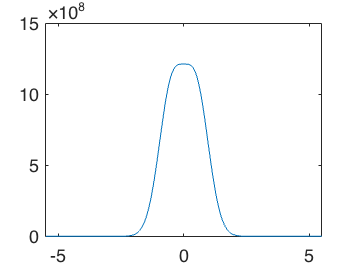

P = zeros(1,length(t));

P = P + signal_power * exp(-(t+Interval*0.5).^2/2/tau_0^2);
P = P + signal_power * exp(-(t-Interval*0.5).^2/2/tau_0^2);
plot(t,P)

Transmission Loss

RLoss = 10^(L*DBLoss/10); %Ratio Loss

Dispersion

for i=1:2^bitnumber

    i = i - 1;
    sequence = dec2binarr(i,bitnumber);

delta_tau = D*delta_lambda*L/1000; %ns
tau = (tau_0.^2 + delta_tau^2).^0.5; % pulse width considering dispersion
Original_Pluse_Energy = signal_power*tau*(2*pi)^0.5;
pulse_energy = Original_Pluse_Energy*RLoss;
average_signal_power = pulse_energy/2/Interval;
P = zeros(1,length(t));

    for ii = 1:bitnumber
        if sequence(ii)==1    
            P_temp = signal_power/tau * exp(-(t+range/2-ii*Interval-2.5*Interval).^2/2/tau^2) * RLoss;
            P = P_temp + P;
        end
    end

P = P * RLoss;
figure(1)
plot(t,P)
hold on

Shot Noise

tstep = 1/fs;  % ns
Uphoton = physconst('LightSpeed')*6.62607015*10^(-34)/wavelwngth * 10^12; %pj
P= tstep * 1e-9 / Uphoton .* P;
figure(2)
plot(t,P)
hold on
P = poissrnd(P);
plot(t,P)

Reciever Noise

NEP = 2; %Units are pW/sqrt(Hz)
Pnoise = NEP * (fs/2*1e9)^0.5;
Nnoise_rms = Pnoise * tstep * 1e-9 / Uphoton;
Nnoise = normrnd(0,Nnoise_rms,[1,length(t)]);
P = P + Nnoise;
SNR = average_signal_power/Nnoise_rms;
SNR_dB = 10*log10(SNR);
figure(3)
plot(t,P)
hold on

Filter

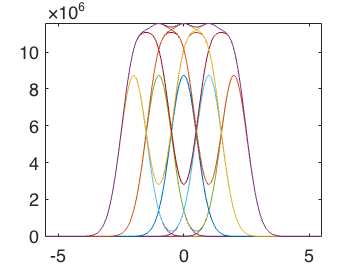

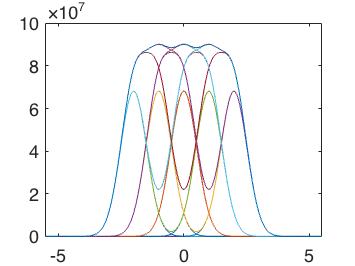

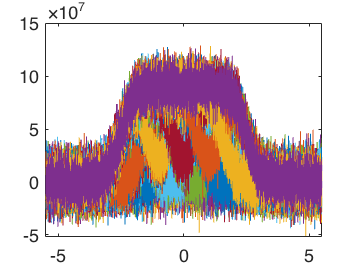

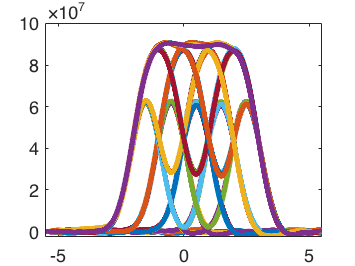

[b,a] = butter(2,fc/(fs/2));

dataIn = P;
P_filt = filter(b,a,P);
figure(4)
plot(t,P_filt,'LineWidth',3)
hold on

end